clear all;

T = 1;
g0 = 2.8;
g1 = 0;

%====================================
k1 = 3.26;
a01 = 1;
T1 = 9.5;
xi = 0.36;
k2 = 1;
a02 = 1;
T2 = 0;

a0 = (a01*a02) / (T1^2);
a1 = (2*xi) / T1;

b0 = k1*k2/(T1^2);

Ac = [0, 1; -a0, -a1];
Bc = [0; 1];
C = [b0, 0];
%C = [1, 0];

A = 0;
k = 100;
for i = 0:k
    A = A + (Ac^i * T^i) / factorial(i);
end
B = 0;
for i = 1:k
    B = B + ((Ac^(i - 1) * T^i) / factorial(i));
end

A;
B = B * Bc;

%===================================================
F_H = [0];
G = [1];

M_H = sylvester(F_H, -A, -G*C);

G_k = [0, 1; 0, 0];
H_k = [1, 0];

M = sylvester(A, -G_k, B*H_k)

M =    -0.5124   -1.5848
    1.0370    1.1067


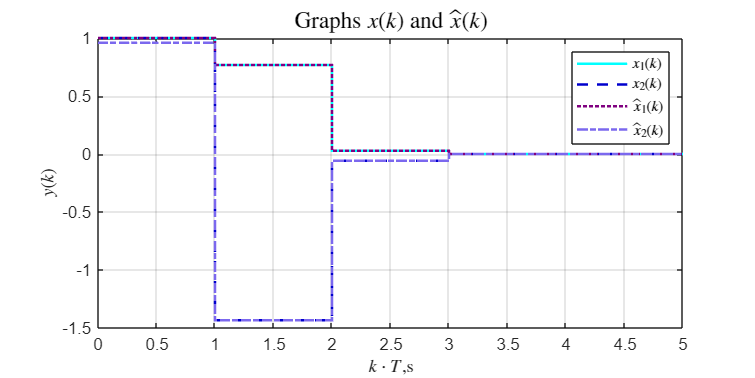

K = H_k * pinv(M);

CM = [C; M_H];
invCM = pinv(CM);
ED = K * invCM;
E = [ED(1)];
D = [ED(2)];

%====================================================


set_param('task_3_schem_1/x', 'VariableName', 'x');
set_param('task_3_schem_1/x_h', 'VariableName', 'x_h');
set_param('task_3_schem_1/y', 'VariableName', 'y');
set_param('task_3_schem_1/e', 'VariableName', 'e');
set_param('task_3_schem_1/z', 'VariableName', 'z');
set_param('task_3_schem_1/z_t', 'VariableName', 'z_t');

out = sim('task_3_schem_1');
t = out.x.Time;
x_h = out.x_h.Data;
x = out.x.Data;
e = out.e.Data;
y = out.y.Data;
z = out.z.Data;
z_t = out.z_t.Data;


% Построение графика

% Определяем цвета для линий
a_color = '#00FFFF'; 
b_color = '#7B68EE';
c_color = '#800080'; 
d_color = '#0000CD';
e_color = '#EE82EE';

figure('Position', [100 100 800 400]);

stairs(t, x(:,1), '-', 'LineWidth', 1.5, 'Color', a_color);
hold on;
stairs(t, x(:,2), '--', 'LineWidth', 1.5, 'Color', d_color);
stairs(t, x_h(:,1), ':', 'LineWidth', 1.5, 'Color', c_color);
stairs(t, x_h(:,2), '-.', 'LineWidth', 1.5, 'Color', b_color);

grid on;

title('Graphs $x(k)$ and $\hat{x}(k)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(k)$','Interpreter', 'latex' );
xlabel('$k \cdot T$,s', 'Interpreter', 'latex');
legend('$x_1(k)$','$x_2(k)$', '$\hat{x}_1(k)$','$\hat{x}_2(k)$','Interpreter', 'latex')
hold off;

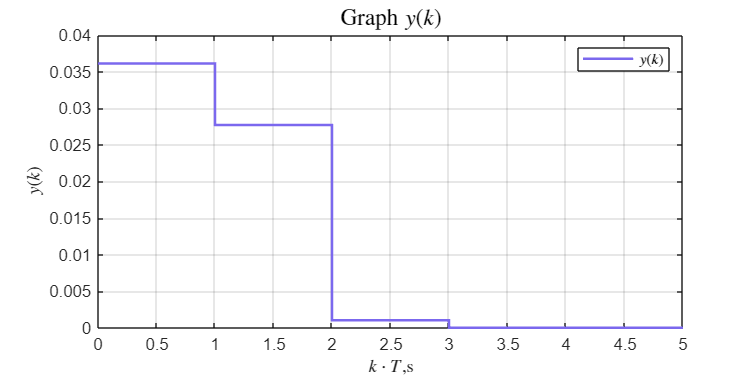


full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_2\Discrete_report_2\pic\' ...
    '3_xxh_1.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);

figure('Position', [100 100 800 400]);
stairs(t, y, '-', 'LineWidth', 1.5, 'Color', b_color);

grid on;

title('Graph $y(k)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(k)$','Interpreter', 'latex' );
xlabel('$k \cdot T$,s', 'Interpreter', 'latex');
legend('$y(k)$','Interpreter', 'latex')
hold off;

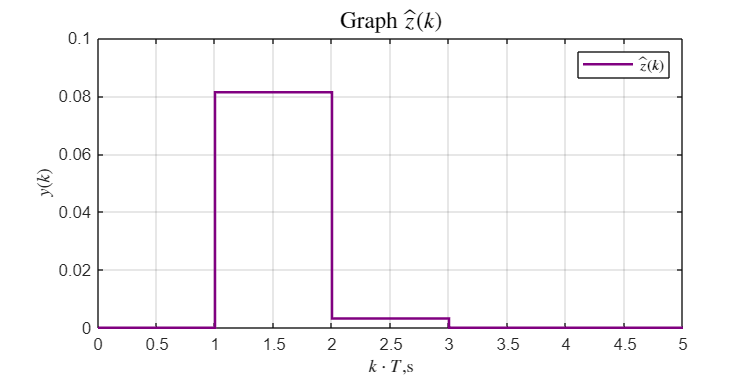


full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_2\Discrete_report_2\pic\' ...
    '3_y_1.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);


figure('Position', [100 100 800 400]);
stairs(t, z, '-', 'LineWidth', 1.5, 'Color', c_color);

grid on;

title('Graph $\hat{z}(k)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(k)$','Interpreter', 'latex' );
xlabel('$k \cdot T$,s', 'Interpreter', 'latex');
legend('$\hat{z}(k)$', 'Interpreter', 'latex')
hold off;

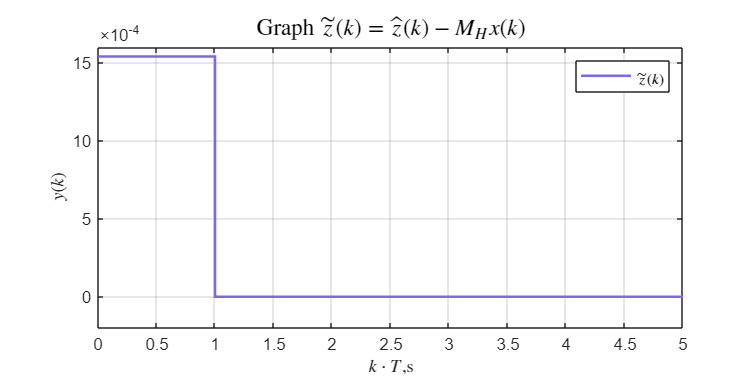


full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_2\Discrete_report_2\pic\' ...
    '3_z_1.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);


figure('Position', [100 100 800 400]);
stairs(t, z_t, '-', 'LineWidth', 1.5, 'Color', b_color);

grid on;

title('Graph $\tilde{z}(k) = \hat{z}(k) - M_H x(k)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(k)$','Interpreter', 'latex' );
xlabel('$k \cdot T$,s', 'Interpreter', 'latex');
legend('$\tilde{z}(k)$','Interpreter', 'latex')
hold off;

full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_2\Discrete_report_2\pic\' ...
    '3_zt_1.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);

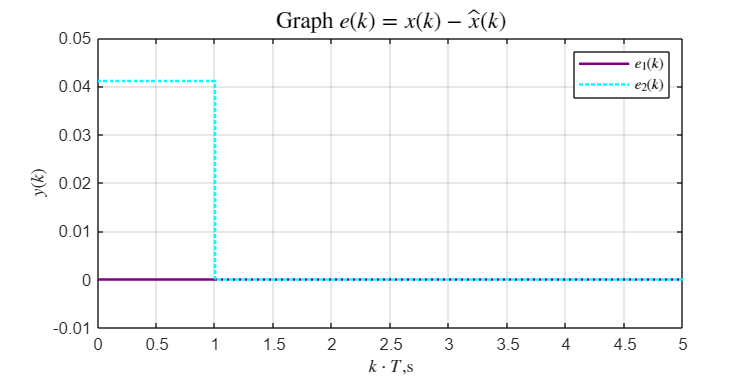



figure('Position', [100 100 800 400]);
stairs(t, e(:, 1), '-', 'LineWidth', 1.5, 'Color', c_color);
hold on;
stairs(t, e(:, 2), ':', 'LineWidth', 1.5, 'Color', a_color);

grid on;

title('Graph $e(k) = x(k) - \hat{x}(k)$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(k)$','Interpreter', 'latex' );
xlabel('$k \cdot T$,s', 'Interpreter', 'latex');
legend('$e_1(k)$','$e_2(k)$','Interpreter', 'latex')
hold off;


full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_2\Discrete_report_2\pic\' ...
    '3_e_1.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);




